syms theta1 theta2 theta3 l1 l2 l3;

frame1  = get_DH_matrix(l1,0,0,theta1);
frame1

$$frame1 = \left(\begin{array}{cccc} \cos\left(\theta_{1}\right) & -\sin\left(\theta_{1}\right) & 0 & l_{1}\,\cos\left(\theta_{1}\right)\\ \sin\left(\theta_{1}\right) & \cos\left(\theta_{1}\right) & 0 & l_{1}\,\sin\left(\theta_{1}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

frame2  = get_DH_matrix(l2,0,0,theta2);
frame2

$$frame2 = \left(\begin{array}{cccc} \cos\left(\theta_{2}\right) & -\sin\left(\theta_{2}\right) & 0 & l_{2}\,\cos\left(\theta_{2}\right)\\ \sin\left(\theta_{2}\right) & \cos\left(\theta_{2}\right) & 0 & l_{2}\,\sin\left(\theta_{2}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

frame3  = get_DH_matrix(l3,0,0,theta3);
frame3

$$frame3 = \left(\begin{array}{cccc} \cos\left(\theta_{3}\right) & -\sin\left(\theta_{3}\right) & 0 & l_{3}\,\cos\left(\theta_{3}\right)\\ \sin\left(\theta_{3}\right) & \cos\left(\theta_{3}\right) & 0 & l_{3}\,\sin\left(\theta_{3}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

q1 = subs(frame1,[l1,theta1],[1,deg2rad(0)]);
q2 = subs(frame2,[l2,theta2],[1,deg2rad(0)]);
q3 = subs(frame3,[l3,theta3],[1,deg2rad(0)]);

final = frame1*frame2*frame3;
final

$$final = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{1} & -\cos\left(\theta_{3}\right)\,\sigma_{3}-\sin\left(\theta_{3}\right)\,\sigma_{2} & 0 & l_{1}\,\cos\left(\theta_{1}\right)+l_{3}\,\cos\left(\theta_{3}\right)\,\sigma_{2}-l_{3}\,\sin\left(\theta_{3}\right)\,\sigma_{3}+l_{2}\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)-l_{2}\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\\ \cos\left(\theta_{3}\right)\,\sigma_{3}+\sin\left(\theta_{3}\right)\,\sigma_{2} & \sigma_{1} & 0 & l_{1}\,\sin\left(\theta_{1}\right)+l_{3}\,\cos\left(\theta_{3}\right)\,\sigma_{3}+l_{3}\,\sin\left(\theta_{3}\right)\,\sigma_{2}+l_{2}\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)+l_{2}\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\theta_{3}\right)\,\sigma_{2}-\sin\left(\theta_{3}\right)\,\sigma_{3}\\ \sigma_{2}=\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)-\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\\ \sigma_{3}=\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)+\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right) \end{array}$$

x = [];
y= [];
z = [];

for i = 0:5:60
    for j = 0:5:45
        for k = 0:5:60

            mat = subs(final,[l1,l2,l3,theta1,theta2,theta3],[1,1,1, deg2rad(i),deg2rad(j),deg2rad(k)]);
            coord = mat(1:3,4);
            x = [x coord(1)];
            y = [y coord(2)];
            z = [z coord(3)];
        end
    end
    disp('Iteration done');
   
end

Iteration done
Iteration done
Iteration done
Iteration done
Iteration done
Iteration done
Iteration done
Iteration done
Iteration done
Iteration done
Iteration done
Iteration done
Iteration done


disp('done');

done


disp(numel(x))

        1690



disp(numel(y))

        1690



disp(numel(z))

        1690



%

disp('2D figure: ');

2D figure: 


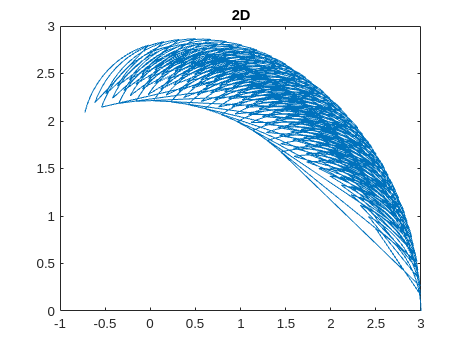

plot(x,y);
title('2D');
hold("off");

figure(2);
plot3(x,y,z);
disp('3D figure: ')

3D figure: 


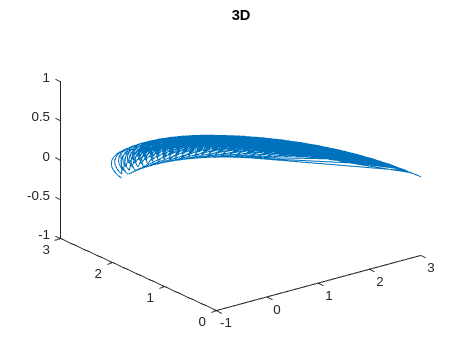

title('3D');

function T = get_DH_matrix(a,alpha,d,theta)
T = [cos(theta) -sin(theta)*cos(alpha) sin(theta)*sin(alpha)  a*cos(theta)
     sin(theta)  cos(theta)*cos(alpha) -cos(theta)*sin(alpha) a*sin(theta)
     0 sin(alpha) cos(alpha) d
     0 0 0 1];
end